clc; clear all; close all; 

% Import Data

mfilename = "Table S5.csv";
dataTable = importDataGroup5(mfilename);

A = dataTable{:,:};

missingMask = ismissing(A);
missingVals  = sum(missingMask);

[missingOrdered, idx] = sort(missingVals, 'descend')

missingOrdered =     30    28    28    25    20    14    12    10    10     6     6     6     6     5     5     5     2     2     2     2     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


idx =     75    37    44    38   109    79   144    41    73    24    46   116   120     6    57   158     7    35    59    63    16    36     1     2     3     4     5     8     9    10    11    12    13    14    15    17    18    19    20    21    22    23    25    26    27    28    29    30    31    32



A(:,idx(1:16))      = [];

% Checking again sample
missingMask         = ismissing(A);
missingValsRow      = sum(missingMask')

missingValsRow =      0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     2     0     1     0     0     0     0     0     0


[missingOrderedRow, idxRow] = sort(missingValsRow, 'descend')

missingOrderedRow =      3     2     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


idxRow =      9    42    16    17    41    44    51     1     2     3     4     5     6     7     8    10    11    12    13    14    15    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    43    45    46    47    48    49


A(idxRow(1:7),:) = []; 

opts = delimitedTextImportOptions("NumVariables", 165);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24", "Var25", "Var26", "Var27", "Var28", "Var29", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var37", "Var38", "Var39", "Var40", "Var41", "Var42", "Var43", "Var44", "Var45", "Var46", "Var47", "Var48", "Var49", "Var50", "Var51", "Var52", "Var53", "Var54", "Var55", "Var56", "Var57", "Var58", "Var59", "Var60", "Var61", "Var62", "Var63", "Var64", "Var65", "Var66", "Var67", "Var68", "Var69", "Var70", "Var71", "Var72", "Var73", "Var74", "Var75", "Var76", "Var77", "Var78", "Var79", "Var80", "Var81", "Var82", "Var83", "Var84", "Var85", "Var86", "Var87", "Var88", "Var89", "Var90", "Var91", "Var92", "Var93", "Var94", "Var95", "Var96", "Var97", "Var98", "Var99", "Var100", "Var101", "Var102", "Var103", "Var104", "Var105", "Var106", "Var107", "Var108", "Var109", "Var110", "Var111", "Var112", "Var113", "Var114", "Var115", "Var116", "Var117", "Var118", "Var119", "Var120", "Var121", "Var122", "Var123", "Var124", "Var125", "Var126", "Var127", "Var128", "Var129", "Var130", "Var131", "Var132", "Var133", "Var134", "Var135", "Var136", "Var137", "Var138", "Var139", "Var140", "Var141", "Var142", "Var143", "Var144", "Var145", "Var146", "Var147", "Var148", "Var149", "Var150", "Var151", "Var152", "Var153", "Var154", "Var155", "Var156", "Var157", "Var158", "Var159", "Var160", "Var161", "Var162", "Var163", "Var164", "Class"];
opts.SelectedVariableNames = "Class";
opts.VariableTypes = ["string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24", "Var25", "Var26", "Var27", "Var28", "Var29", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var37", "Var38", "Var39", "Var40", "Var41", "Var42", "Var43", "Var44", "Var45", "Var46", "Var47", "Var48", "Var49", "Var50", "Var51", "Var52", "Var53", "Var54", "Var55", "Var56", "Var57", "Var58", "Var59", "Var60", "Var61", "Var62", "Var63", "Var64", "Var65", "Var66", "Var67", "Var68", "Var69", "Var70", "Var71", "Var72", "Var73", "Var74", "Var75", "Var76", "Var77", "Var78", "Var79", "Var80", "Var81", "Var82", "Var83", "Var84", "Var85", "Var86", "Var87", "Var88", "Var89", "Var90", "Var91", "Var92", "Var93", "Var94", "Var95", "Var96", "Var97", "Var98", "Var99", "Var100", "Var101", "Var102", "Var103", "Var104", "Var105", "Var106", "Var107", "Var108", "Var109", "Var110", "Var111", "Var112", "Var113", "Var114", "Var115", "Var116", "Var117", "Var118", "Var119", "Var120", "Var121", "Var122", "Var123", "Var124", "Var125", "Var126", "Var127", "Var128", "Var129", "Var130", "Var131", "Var132", "Var133", "Var134", "Var135", "Var136", "Var137", "Var138", "Var139", "Var140", "Var141", "Var142", "Var143", "Var144", "Var145", "Var146", "Var147", "Var148", "Var149", "Var150", "Var151", "Var152", "Var153", "Var154", "Var155", "Var156", "Var157", "Var158", "Var159", "Var160", "Var161", "Var162", "Var163", "Var164"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24", "Var25", "Var26", "Var27", "Var28", "Var29", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var37", "Var38", "Var39", "Var40", "Var41", "Var42", "Var43", "Var44", "Var45", "Var46", "Var47", "Var48", "Var49", "Var50", "Var51", "Var52", "Var53", "Var54", "Var55", "Var56", "Var57", "Var58", "Var59", "Var60", "Var61", "Var62", "Var63", "Var64", "Var65", "Var66", "Var67", "Var68", "Var69", "Var70", "Var71", "Var72", "Var73", "Var74", "Var75", "Var76", "Var77", "Var78", "Var79", "Var80", "Var81", "Var82", "Var83", "Var84", "Var85", "Var86", "Var87", "Var88", "Var89", "Var90", "Var91", "Var92", "Var93", "Var94", "Var95", "Var96", "Var97", "Var98", "Var99", "Var100", "Var101", "Var102", "Var103", "Var104", "Var105", "Var106", "Var107", "Var108", "Var109", "Var110", "Var111", "Var112", "Var113", "Var114", "Var115", "Var116", "Var117", "Var118", "Var119", "Var120", "Var121", "Var122", "Var123", "Var124", "Var125", "Var126", "Var127", "Var128", "Var129", "Var130", "Var131", "Var132", "Var133", "Var134", "Var135", "Var136", "Var137", "Var138", "Var139", "Var140", "Var141", "Var142", "Var143", "Var144", "Var145", "Var146", "Var147", "Var148", "Var149", "Var150", "Var151", "Var152", "Var153", "Var154", "Var155", "Var156", "Var157", "Var158", "Var159", "Var160", "Var161", "Var162", "Var163", "Var164", "Class"], "EmptyFieldRule", "auto");

% Import the data
class = readtable("Table S5.csv", opts)

class = 60×1 table
     Class 
    _______

    Control
    Control
    Control
    Control
    Control
    Control
    Control
    Control
    Control
    Control
    Control
    Control
    Control
    Control
    Control
    Control


clear opts 
class = categorical(class.Class);

class(idxRow(1:7)) = [];


## Make full PCA model

% Center and scale data
model(1).X0     = A(class=="Control",:);
[row, col]      = size(A);
model(1).name   = "healthy";
X0Diab          = A(class=="diabetes",:);

[model(1).X, model(1).mu, model(1).sigma] = zscore(model(1).X0);
model(1).Xtest = normalize(X0Diab, 'Center', model(1).mu, 'Scale', model(1).sigma);

% Form initial PCA model 
[model(1).P, model(1).T, model(1).latent, model(1).T2, model(1).expl] = pca(model(1).X, 'Centered',false);

## Explained variance

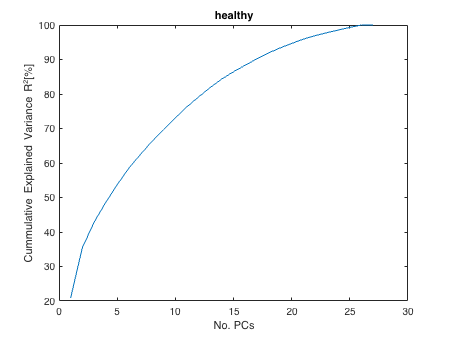

i = 1;
model(i).explVar = 100 * cumsum(model(i).latent) / sum(model(i).latent);
plot(1:length(model(i).explVar), model(i).explVar)
xlabel("No. PCs"); ylabel("Cummulative Explained Variance R^2[%]");
title(model(i).name);

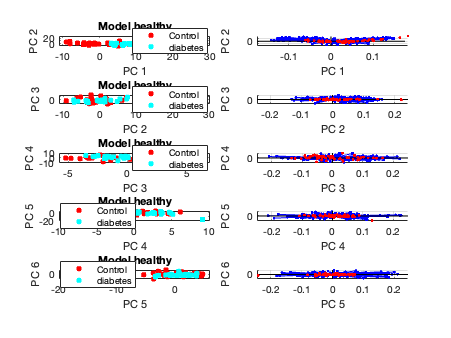

model(i).Ttest = model(i).Xtest * model(i).P;

[row, ~] = size(A);
[~, col1] = size(model(1).T);
dummy1 = ones(row, col1); model(1).Tcomb = dummy1;
model(1).Tcomb(class=="Control", :) = model(1).T;
model(1).Tcomb(class=="diabetes",:) = model(1).Ttest;

figure;
ii = 1;

for i = 1:5
    subplot(5,2,ii);
    gscatter(model(1).Tcomb(:,i), model(1).Tcomb(:, i+1), class);
    text1 = "PC " + string(i);
    text2 = "PC " + string(i+1);
    xlabel(text1); ylabel(text2);
    ii = ii + 1;
    title("Model " + model(1).name);

    subplot(5,2,ii);
    biplot(model(1).P(:,i:i+1), 'Scores', model(1).Tcomb(:,i:i+1));
    xlabel(text1); ylabel(text2);
    ii = ii + 1;
end

## Control charts

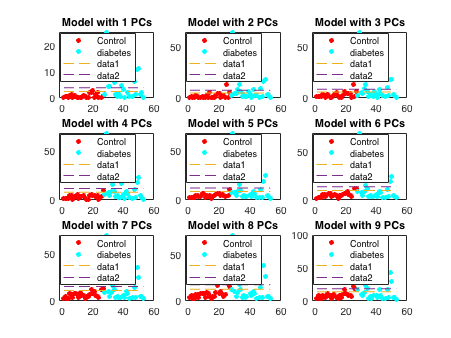

model(1).Xext = [model(1).X; model(1).Xtest];

for j = 1:27
    model(1).comps(j).T2 = t2comp(model(1).Xext, model(1).P, model(1).latent, j);
    model(1).comps(j).T2lim1 = mean(model(1).comps(j).T2(class=="Control")) + 1 * std(model(1).comps(j).T2(class=="Control"));
    model(1).comps(j).T2lim2 = mean(model(1).comps(j).T2(class=="Control")) + 2 * std(model(1).comps(j).T2(class=="Control"));
end

figure; 
for j = 1:9
    subplot(3,3,j);
    gscatter(1:row, model(1).comps(j).T2, class);
    hold on
    plot([1 row], [model(1).comps(j).T2lim1, model(1).comps(j).T2lim1], "--");
    plot([1 row], [model(1).comps(j).T2lim2, model(1).comps(j).T2lim2], "--");
    title("Model with " + string(j) + " PCs");
end

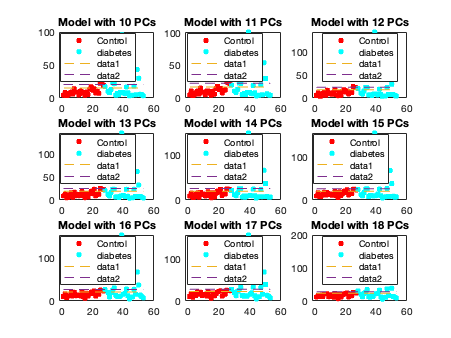


figure;
ii = 1;
for j = 10:18
    subplot(3,3,ii);
    ii = ii + 1;
    gscatter(1:row, model(1).comps(j).T2, class);
    hold on
    plot([1 row], [model(1).comps(j).T2lim1, model(1).comps(j).T2lim1], "--");
    plot([1 row], [model(1).comps(j).T2lim2, model(1).comps(j).T2lim2], "--");
    title("Model with " + string(j) + " PCs");
end

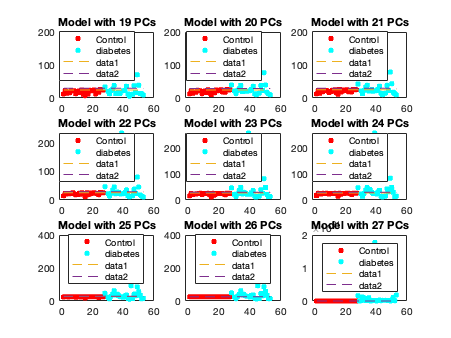

figure; ii = 1;
for j = 19:27
    subplot(3,3,ii);
    ii = ii + 1;
    gscatter(1:row, model(1).comps(j).T2, class);
    hold on
    plot([1 row], [model(1).comps(j).T2lim1, model(1).comps(j).T2lim1], "--");
    plot([1 row], [model(1).comps(j).T2lim2, model(1).comps(j).T2lim2], "--");
    title("Model with " + string(j) + " PCs");
end

## Control Charts for SPEx

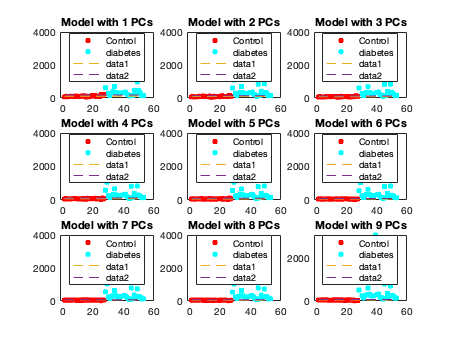

for j = 1:27
    model(1).comps(j).Q = qcomp(model(1).Xext, model(1).P, j);
    model(1).comps(j).Qlim1 = mean(model(1).comps(j).Q(class=="Control")) + 0.01 * std(model(1).comps(j).Q(class=="Control"));
    model(1).comps(j).Qlim2 = mean(model(1).comps(j).Q(class=="Control")) + 2 * std(model(1).comps(j).Q(class=="Control"));
end

figure; 
for j = 1:9
    subplot(3,3,j);
    gscatter(1:row, model(1).comps(j).Q, class);
    hold on
    plot([1 row], [model(1).comps(j).Qlim1, model(1).comps(j).Qlim1], "--");
    plot([1 row], [model(1).comps(j).Qlim2, model(1).comps(j).Qlim2], "--");
    title("Model with " + string(j) + " PCs");
end

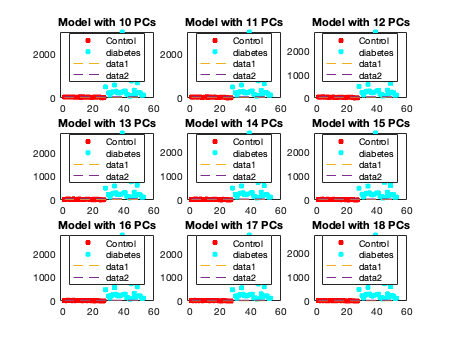


figure;
ii = 1;
for j = 10:18
    subplot(3,3,ii);
    ii = ii + 1;
    gscatter(1:row, model(1).comps(j).Q, class);
    hold on
    plot([1 row], [model(1).comps(j).Qlim1, model(1).comps(j).Qlim1], "--");
    plot([1 row], [model(1).comps(j).Qlim2, model(1).comps(j).Qlim2], "--");
    title("Model with " + string(j) + " PCs");
end

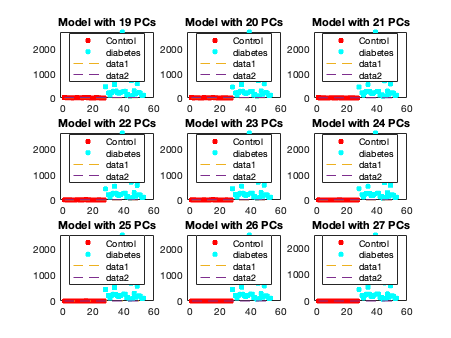

figure; ii = 1;
for j = 19:27
    subplot(3,3,ii);
    ii = ii + 1;
    gscatter(1:row, model(1).comps(j).Q, class);
    hold on
    plot([1 row], [model(1).comps(j).Qlim1, model(1).comps(j).Qlim1], "--");
    plot([1 row], [model(1).comps(j).Qlim2, model(1).comps(j).Qlim2], "--");
    title("Model with " + string(j) + " PCs");
end

## Contributions to SPEx and Q

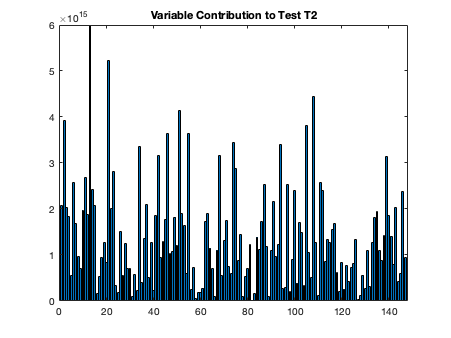


model(1).T2ContrTest    = t2contr(model(1).Xtest, model(1).P, model(1).latent, 27);
figure;
bar(model(1).T2ContrTest);
title("Variable Contribution to Test T2")

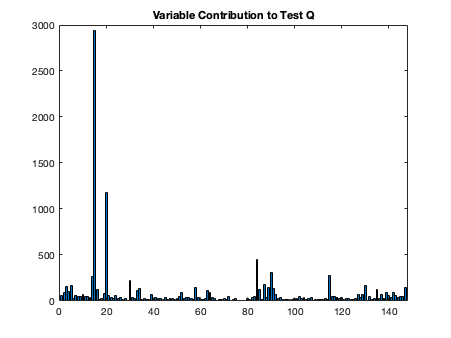



model(1).QContrTest     = qcontr(model(1).Xtest, model(1).P, 6);
figure;
bar(model(1).QContrTest);
title("Variable Contribution to Test Q")

## Selection of variables

idxVarsT2       = find(model(1).T2ContrTest>2.5*10^15);
idxVarsQ        = find(model(1).QContrTest>130);
idxVarsCommon   = intersect(idxVarsT2,idxVarsQ);


## Reforming PCA models

model(2).X = model(1).X(:,idxVarsT2);
model(2).name = "T2 Variable Selection";

model(3).X = model(1).X(:,idxVarsCommon);
model(3).name = "Common T2 and Q";

model(4).X = model(1).X(:, idxVarsQ);
model(4).name = "Q Variable Selection";

for i = 2:4
    [model(i).P, model(i).T, model(i).latent, model(i).tsq, model(i).explained] = pca(model(i).X, 'Centered', false);
    model(i).explVar = 100 * cumsum(model(i).latent) / sum(model(i).latent);
end


## Explained variance of models

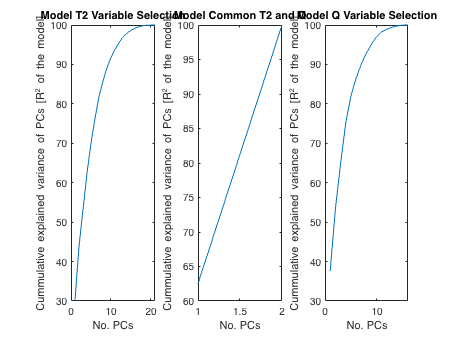

figure; ii = 1;
for i = 2:4
    subplot(1, 3, ii); ii = ii + 1;
    plot(model(i).explVar);
    title("Model " + model(i).name);
    xlabel("No. PCs");
    ylabel("Cummulative explained variance of PCs [R^2 of the model]");
end

## Projecting Scores

model(2).Xtest = model(1).Xtest(:,idxVarsT2);
model(3).Xtest = model(1).Xtest(:,idxVarsCommon);
model(4).Xtest = model(1).Xtest(:, idxVarsQ);

for i = 2:4
    model(i).Ttest  = model(i).Xtest * model(i).P;
    model(i).Tcomb  = [model(i).T; model(i).Ttest];
end


## Biplots

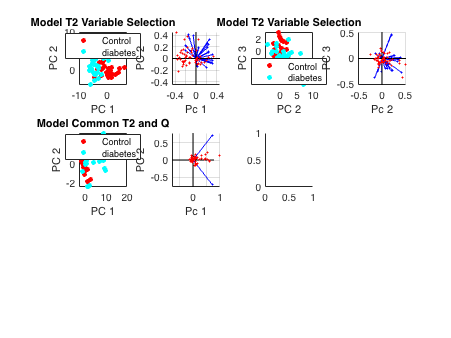

Index in position 2 exceeds array bounds. Index must not exceed 2.

figure; ii = 1;
for i = 2:4
    subplot(3,4,ii); ii = ii + 1;
    gscatter(model(i).Tcomb(:,1), model(i).Tcomb(:,2), class);
    xlabel("PC 1");
    ylabel("PC 2");
    title("Model " + model(i).name);

    subplot(3,4,ii); ii = ii + 1;
    biplot(model(i).P(:, 1:2), 'Scores', model(i).Tcomb(:,1:2));
    xlabel("Pc 1");
    ylabel("PC 2");

    subplot(3,4,ii); ii = ii + 1;
    gscatter(model(i).Tcomb(:,2), model(i).Tcomb(:,3), class);
    xlabel("PC 2");
    ylabel("PC 3");
    title("Model " + model(i).name);

    subplot(3,4,ii); ii = ii + 1;
    biplot(model(i).P(:, 2:3), 'Scores', model(i).Tcomb(:,2:3));
    xlabel("Pc 2");
    ylabel("PC 3");
end

## Computing T2 control charts

for i = 2:4
    model(i).Xext = [model(i).X; model(i).Xtest];
    
    for j = 1:3
        model(i).comps(j).T2 = t2comp(model(i).Xext, model(i).P, model(i).latent, j);
        model(i).comps(j).T2lim1 = mean(model(i).comps(j).T2(class=="Control")) + 1 * std(model(i).comps(j).T2(class=="Control"));
        model(i).comps(j).T2lim2 = mean(model(i).comps(j).T2(class=="Control")) + 2 * std(model(i).comps(j).T2(class=="Control"));

        model(i).comps(j).Q = qcomp(model(i).Xext, model(i).P, j);
        model(i).comps(j).Qlim1 = mean(model(i).comps(j).Q(class=="Control")) + 0.01 * std(model(i).comps(j).Q(class=="Control"));
        model(i).comps(j).Qlim2 = mean(model(i).comps(j).Q(class=="Control")) + 2 * std(model(i).comps(j).Q(class=="Control"));
    end
end


## Plotting Charts

figure; ii = 1;
for i = 2:4
for j = 1:3
    subplot(3,3,ii); ii = ii + 1;
    gscatter(1:row, model(i).comps(j).T2, class);
    hold on
    plot([1 row], [model(i).comps(j).T2lim1, model(i).comps(j).T2lim1], "--");
    plot([1 row], [model(i).comps(j).T2lim2, model(i).comps(j).T2lim2], "--");
    title("Model " + model(i).name + " with " + string(j) + " PCs");
    ylabel("T2");
end
end

figure; ii = 1;
for i = 2:4
for j = 1:3
    subplot(3,3,ii); ii = ii + 1;
    gscatter(1:row, model(i).comps(j).Q, class);
    hold on
    plot([1 row], [model(i).comps(j).Qlim1, model(i).comps(j).Qlim1], "--");
    plot([1 row], [model(i).comps(j).Qlim2, model(i).comps(j).Qlim2], "--");
    title("Model " + model(i).name + " with " + string(j) + " PCs");
    ylabel("Q");
end
end

## Function

function T2     = t2comp(data, loadings, latent, comp)
        score       = data * loadings(:,1:comp);
        standscores = bsxfun(@times, score(:,1:comp), 1./sqrt(latent(1:comp,:))');
        T2          = sum(standscores.^2,2);
end

% SPEx
function [lev, levlim]=leveragex(T)
% INPUT:
% 	T =  X scores
% OUTPUT:
% 	lev = leverage values (X space)
%   levlim = approximation for 95 % confidence limits

lev = zeros(length(T),1);
[m,~] = size(T);
for i=1:m
    lev(i,1)=T(i,:)*inv(T'*T)*T(i,:)'+1/length(T); %#ok<MINV>
end
plot(lev,'-o');hold on
levlim=2*length(T(1,:))/length(T(:,1));
plot([1,length(T)],[levlim levlim]','-');
hold off
end

function T2varcontr    = t2contr(data, loadings, latent, comp)
score           = data * loadings(:,1:comp);
standscores     = bsxfun(@times, score(:,1:comp), 1./sqrt(latent(1:comp,:))');
T2contr         = abs(standscores*loadings(:,1:comp)');
T2varcontr      = sum(T2contr,1);
end

function Qcontr   = qcontr(data, loadings, comp)
score         = data * loadings(:,1:comp);
reconstructed = score * loadings(:,1:comp)';
residuals     = bsxfun(@minus, data, reconstructed);
Qcontr        = sum(residuals.^2);
end

function Qfac   = qcomp(data, loadings, comp)
score       = data * loadings(:,1:comp);
reconstructed = score * loadings(:,1:comp)';
residuals   = bsxfun(@minus, data, reconstructed);
Qfac        = sum(residuals.^2,2);
end
